# Random walk 3D

function [path] = RandomWalk(num_steps, starting_radius, min_step, max_step)
phi = deg2rad(randi(360, 1, 1));
theta = deg2rad(randi(180, 1, 1));
position = starting_radius * [sin(theta) * cos(phi) sin(theta) * sin(phi) cos(theta)];
path = zeros(num_steps + 1, 3);
path(1, :) = position;

for i = 1:num_steps
    phi = deg2rad(randi(360, 1, 1));
    theta = deg2rad(randi(180, 1, 1));
    radius = randsample(min_step:0.1:max_step, 1);
    step =  radius * [sin(theta) * cos(phi) sin(theta) * sin(phi) cos(theta)];
    position = position + step;
    path(i + 1, :) = [position];
end
end

## Random walks

num_paths = 50;
num_steps = 50;
start_radius = 3;
min_step = 0;
max_step = 1;

tic
for i = 1:num_paths
    i
    path = RandomWalk(num_steps, start_radius, min_step, max_step);
    scatter3(path(1, 1), path(1, 2), path(1, 3), 30, "black", "MarkerFaceColor", 'black');
    plot3(path(:, 1), path(:, 2), path(:, 3));
    hold on
    axis equal
end

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

i = 27

i = 28

i = 29

i = 30

i = 31

i = 32

i = 33

i = 34

i = 35

i = 36

i = 37

i = 38

i = 39

i = 40

i = 41

i = 42

i = 43

i = 44

i = 45

i = 46

i = 47

i = 48

i = 49

i = 50

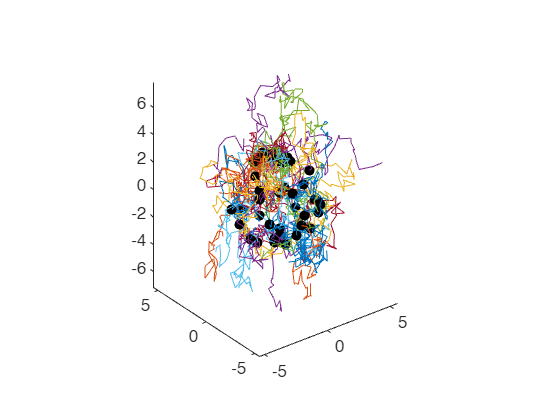

hold off

toc

Elapsed time is 2.369986 seconds.


## Prellocating

A = zeros(3, 3);
A(2, :) = [1 2 3];